# Exercise 5

## Commanding the Robot Using Differential Drive

### About This Exercise

Time to get moving! Moving the robot from one position to the next would be easy if you could just move in any direction, regardless of orientation. For example, it would be nice if you could drive your car sideways and easily fit into a tight parking spot. In reality, you have to follow a complicated set of maneuvers to move your car in just the right way so that you do not hit the curb or stick into the street as you fit into the spot. Many mobile robots have the same constraint of not being able to move laterally, or in other words, have limited controllable degrees of freedom. While the Create robot has three degrees of freedom (x, y, and orientation) it can only be controlled using using the forward and angular velocity, therefore two controllable degrees of freedom. Robots that have less controllable degrees of freedom than the total degrees of freedom are called non-holonomic robots. One type of non-holonomic robots are Differential drive robots, like the one in our simulator, have two driving wheels, one on either side of the robot, and likely some free moving casters for balance. The two wheels can be controlled independently, and thus they can drive the robot in any circular arc forward or backward. 

You will explore the equations relating the movement of the wheels to the movement of the robot in this exercise. In the next exercise, you will learn how to control the wheels to actually get from one point to another in the map.

**By the end of this exercise, you'll be able to: **

- **Code the equations necessary to control the movement of a non-holonomic and differential drive robot.**

- **Write a function to limit control inputs sent to the robot.**

- **Write a fucntion to find a path for the robot to reach a goal.**

*Remember to connect with your peers and the course facilitator if you get stuck or need help working through any part of this exercise.*

### Tank-like Controls

Eventually we would like to be able to command the forward/backward velocity $V$ of the robot as well as its angular velocity $\omega$. However, we only have control over the rotational speed of the left and right wheels (which we call $u_l$ and $u_r$) similar to how a tank is driven. Let's step through the relationships between the two pairs of variables.

Before diving into the code or equations, let's build some intuition. If we command the wheels to spin in the same direction at the same speed, assuming both wheels do not slip, are the same size, and sit symmetrically on the robot, how will the robot move? What about if the two wheels spin the same speed in opposite directions? These two examples represent the extremes of the range of arcs the robot can follow, from one with infinite radius (i.e., a straight line) to one with zero radius (i.e., spinning in place). In general, the instantaneous movement of the robot center will follow some arc with radius $R$, where $R = V/\omega$. This intuition behind this equation is that the faster the robot moves forward relative to the speed that it turns, the straighter it will go and therefore the arc radius will be large.

While throughout the course you will simply command $V$ and $\omega$, it is useful to understand the relationship between those command and the corresponding wheel speeds for two reasons. First, to actually implement the control on a real robot, you will need to know what command to give each wheel given $V$ and $\omega$. Second, the speed of the wheels has a maximum limit, so we need to understand how that contraint, constrains $V$ and $\omega$. Let's step through those steps now.

First let's define a few robot constants:

L = 0.26; % Distance between wheels in meters
r = 0.05; % Wheel radius in meters

Next, define u_r and u_l, which are the commanded wheel rotational speeds for the left and right wheels (in rad/s). 

u_l = pi;%  per second
u_r = pi/2;%  per second

v_l and v_r are the resulting translational wheel velocities, calculated by the equations $v =   ur$. This equation assumes no slip between the wheel and ground.

**Complete the code below.**

v_l = u_l*r; %(m/s)
v_r = u_r*r; %(m/s)


omega is the angular velocity of the robot (positive is counterclockwise where the right wheel moves faster) given by the equation $\omega = \frac{v_r - v_l}{L}$

**Complete the code below.**

omega = (v_r - v_l)/L; %radians per second

V is the translational speed of the robot given by $V = \frac{v_r + v_l}{2}$, which is the average translational speed of both wheels.

**Complete the code below.**

V = (v_r+v_l)/2; %(m/s)

R is the radius of the arc given by $R = V/\omega$ as described above

**Complete the code below.**

R = V/omega;%(m)

The above equations can be put together into matrix form representing the system of two equations given by


$$\left[\matrix{V \cr \omega}\right] = \left[\matrix{\frac{r}{2} & \frac{r}{2} \cr \frac{r}{L} & -\frac{r}{L}}\right] \left[\matrix{u_r \cr u_l}\right]$$



$$\left[\matrix{V \cr \omega}\right] = A u$$


which directly relate the wheel rotational speeds $u_r$ and $u_l$ to the robot velocities $V$ and $\omega$ we would like to control. This matrix formulation also allows us to calculate $u_r$ and $u_l$ from $V$ and $\omega$ using the inverse of the 2-by-2 matrix above (which we'll set as the variable A).

Try different values for $u_l$ and $u_r$, and update the plot to see how the robot and its wheels velocities will be updated. The red line shows the path the robot will take for the next 1 second given these controls.

u_l =1.1; 
u_r =1.3;

**Complete the code below.**

A = [r/2, r/2; r/L, -r/L];

Test:

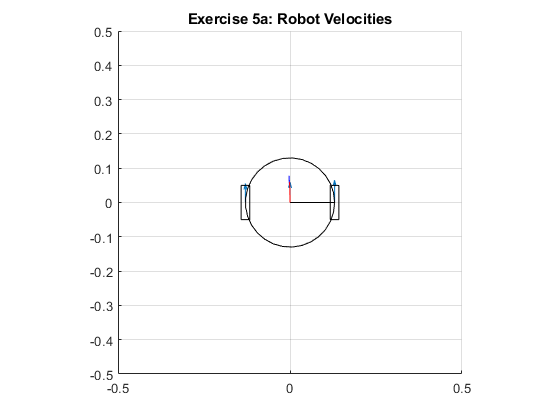

robotVelocities = A*[u_r;u_l]; 
V = robotVelocities(1);
omega = robotVelocities(2);
plot_title = "Exercise 5a"; 
plot_robot(u_r,u_l,V,omega,L,r, plot_title);

## Getting commanded wheel speeds from desired robot translational and rotational velocities

We would like to be able to do the inverse operation, that is going from robot velocities V and omega to wheel rotational velocities u. You can either solve the equations for u_l and u_r by hand, or if you already have the matrix version you can simply use the inverse operation you've learned previously (the \ operator)

V =0.5;
omega =0.5;

**Complete the code below.**

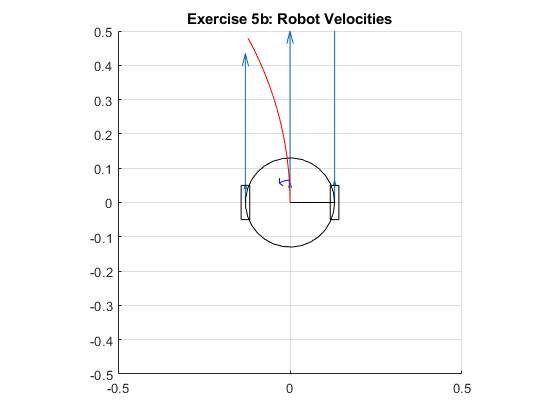

u = A\[V; omega];
plot_title = "Exercise 5b"; 
plot_robot(u(1),u(2),V,omega,L,r, plot_title);

## Adjust control inputs based on limits

A desired $V,\omega$ pair might result in commanded wheel velocities that exceed their capabilities, denoted by $u_{max}$. For example, you might have noticed that if $\omega$ is maxed out, small changes to $V$ will result in wheel speed $u$ that exceeds the limits of the plot (which you might interpret as $u_{max}$). However, we can scale both $V$ and $\omega$ by the same factor and maintain the same radius $R$, thus following along the same path, albiet at a different speed. Given the linear relationship between the wheel velocities and the robot velocities, scaling the wheel velocities by a certain factor will scale the robot velocities by the same factor.

[► Complete the limitCommands function](matlab:open('./limitCommands.mlx')) to implement this limit, where you will input $V$, $\omega$, and $u_{max}$, and output $V_{scaled}$ and $\omega_{scaled}$.

Once complete, the following code will **test** your function. The left plot is pre-scaling and the right is post-scaling. However, the red arc should have the same curvatuve, but should be shorter if the velocities are scaled as the robot will move slower and therefore a shorter distance in 1 second.

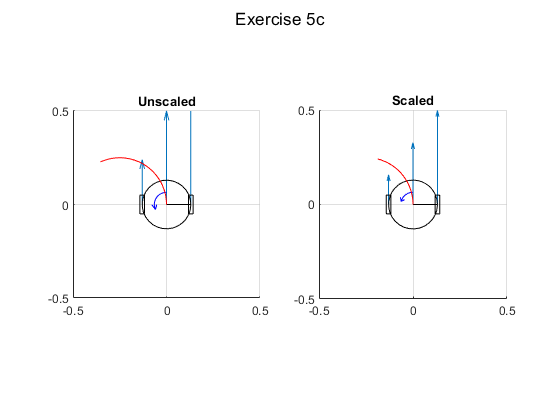

V =0.5;
omega =2;
maxWheelSpeed =10;
u = A\[V;omega]; % This assumes your A matrix above is correct
subplot(1,2,1)
plot_robot(u(1),u(2),V,omega,L,r,"");
title('Unscaled')
[V,omega,scaleFactor] = limitCommands(V,omega,maxWheelSpeed); % This tests your function
u = A\[V;omega];
subplot(1,2,2)
plot_robot(u(1),u(2),V,omega,L,r,"");
title('Scaled')
plot_title = "Exercise 5c"; 
sgtitle(plot_title); 

scaleFactor % Displays the scale factor in the output

scaleFactor = 0.6579

## Compute an Arc Trajectory

You've seen how you can choose the robot velocities needed to follow an arc and limit those velocities according to the wheel constraints. Now, how do you choose the arc radius to get to where you want to go? Luckily, if you have a starting pose and a goal position, there is only one circle connecting the two and you can calculate that radius. 

[► Create the function findArcPath](matlab:open('./findArcPath.mlx')) that will take in the current pose, goal position, and the max wheel speed and return the V, omega, and time to drive the robot to the goal. Once finished, **test** it with this section. The green dot that represents the goal point should match up with the final position of the robot over it's trajectory. Use the sliders to change the goal point as well as the starting orientation.

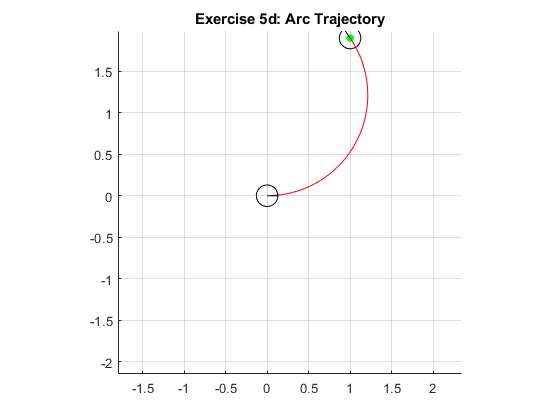

figure; 
goal_x =1;
goal_y =1.9;
starting_orientation = 0;
goal_xy = [goal_x,goal_y];
pose_begin = [0, 0, starting_orientation];
maxWheelSpeed = 10;
[V,omega,time] = findArcPath(pose_begin, goal_xy,maxWheelSpeed);
plot_title = "Exercise 5d"; 
plot_arc(V,omega, pose_begin, goal_xy,time, plot_title)

xlim([-1.79 2.34])
ylim([-2.15 1.98])

Running the script below will generate a new interactive figure, where you can see many goal points all at one time and change the starting orientation. Note that a new figure window will pop up that has the working slider, the figure that plots in the normal output to the right is a static image.

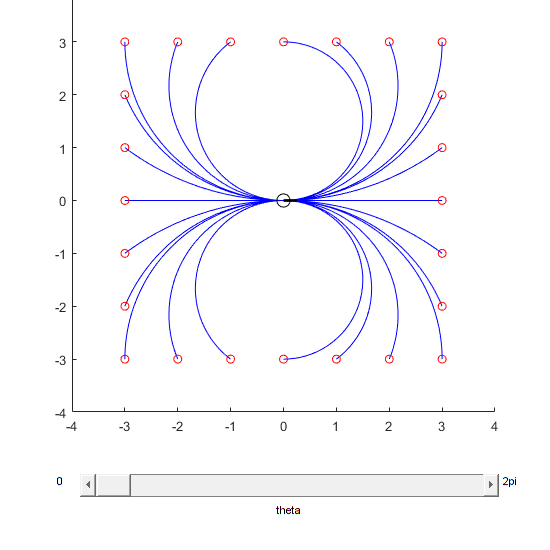

plotArcTrajs;

### Finished!

You have now achieved movement from one place to another. However, finding the arc connecting two points is just one strategy for moving around. It cannot account for errors in movement along the trajectory, and it may not necessarily be the most optimal trajectory. In the next exercise, we will investigate a feedback strategy that updates the commanded $V$ and $\omega$ according to the continuously updated pose of the robot.